# Find Line Segments and Highlight longest segment

Read image into workspace.

I  = imread('circuit.tif');

Rotate the image.

rotI = imrotate(I,33,'crop');

Create a binary image.

BW = edge(rotI,'canny');

Create the Hough transform using the binary image.

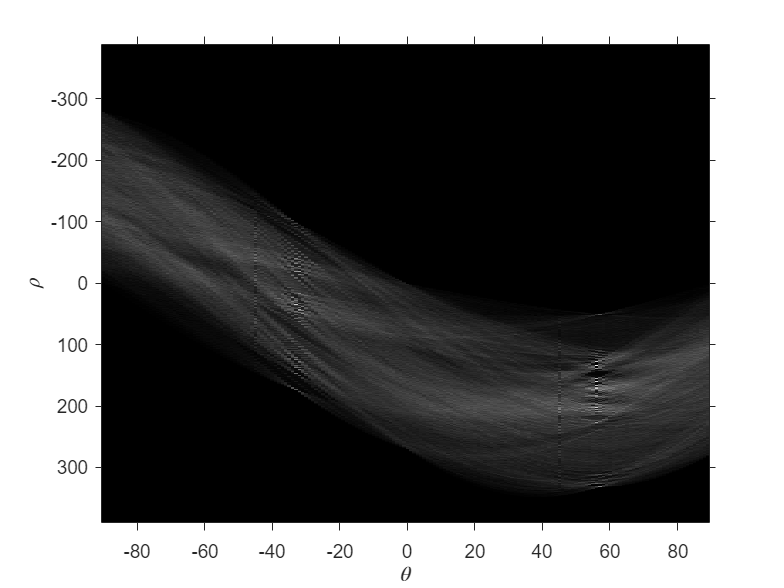

[H,T,R] = hough(BW);
imshow(H,[],'XData',T,'YData',R,...
            'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;

Find peaks in the Hough transform of the image.

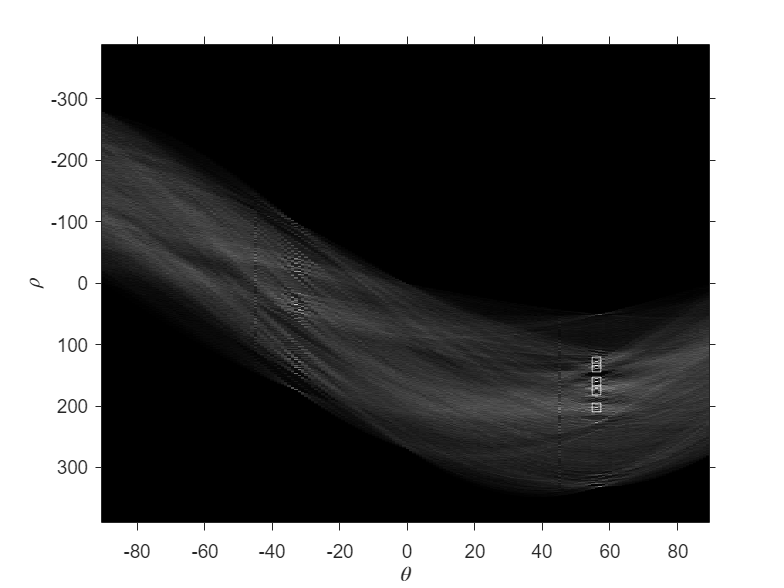

P  = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
x = T(P(:,2)); y = R(P(:,1));
plot(x,y,'s','color','white');

Find lines and plot them.

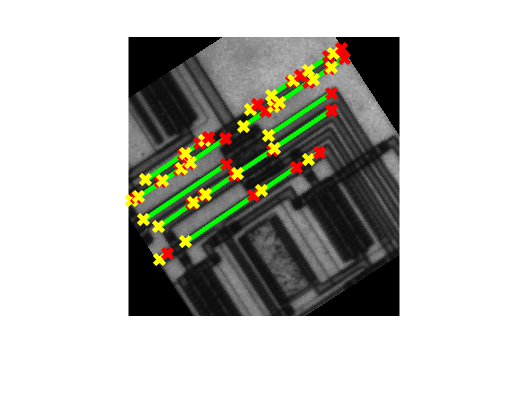

lines = houghlines(BW,T,R,P,'FillGap',2,'MinLength',5);
figure, imshow(rotI), hold on
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end

Highlight the longest line segment by coloring it cyan.

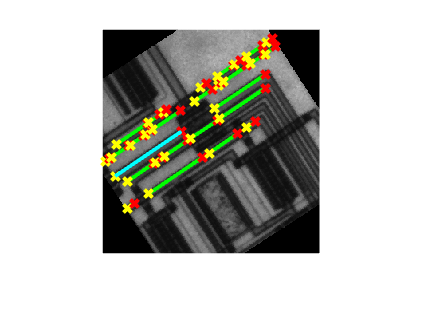

plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','cyan');

*Copyright 2015 The MathWorks, Inc.*